`Erfan Panahi 810198369`

## `Digital Communication`

# `Computer Assignement #3`

clc
clear 
close all

`Part 1. (``Generate Raised-cosine pulse``)`

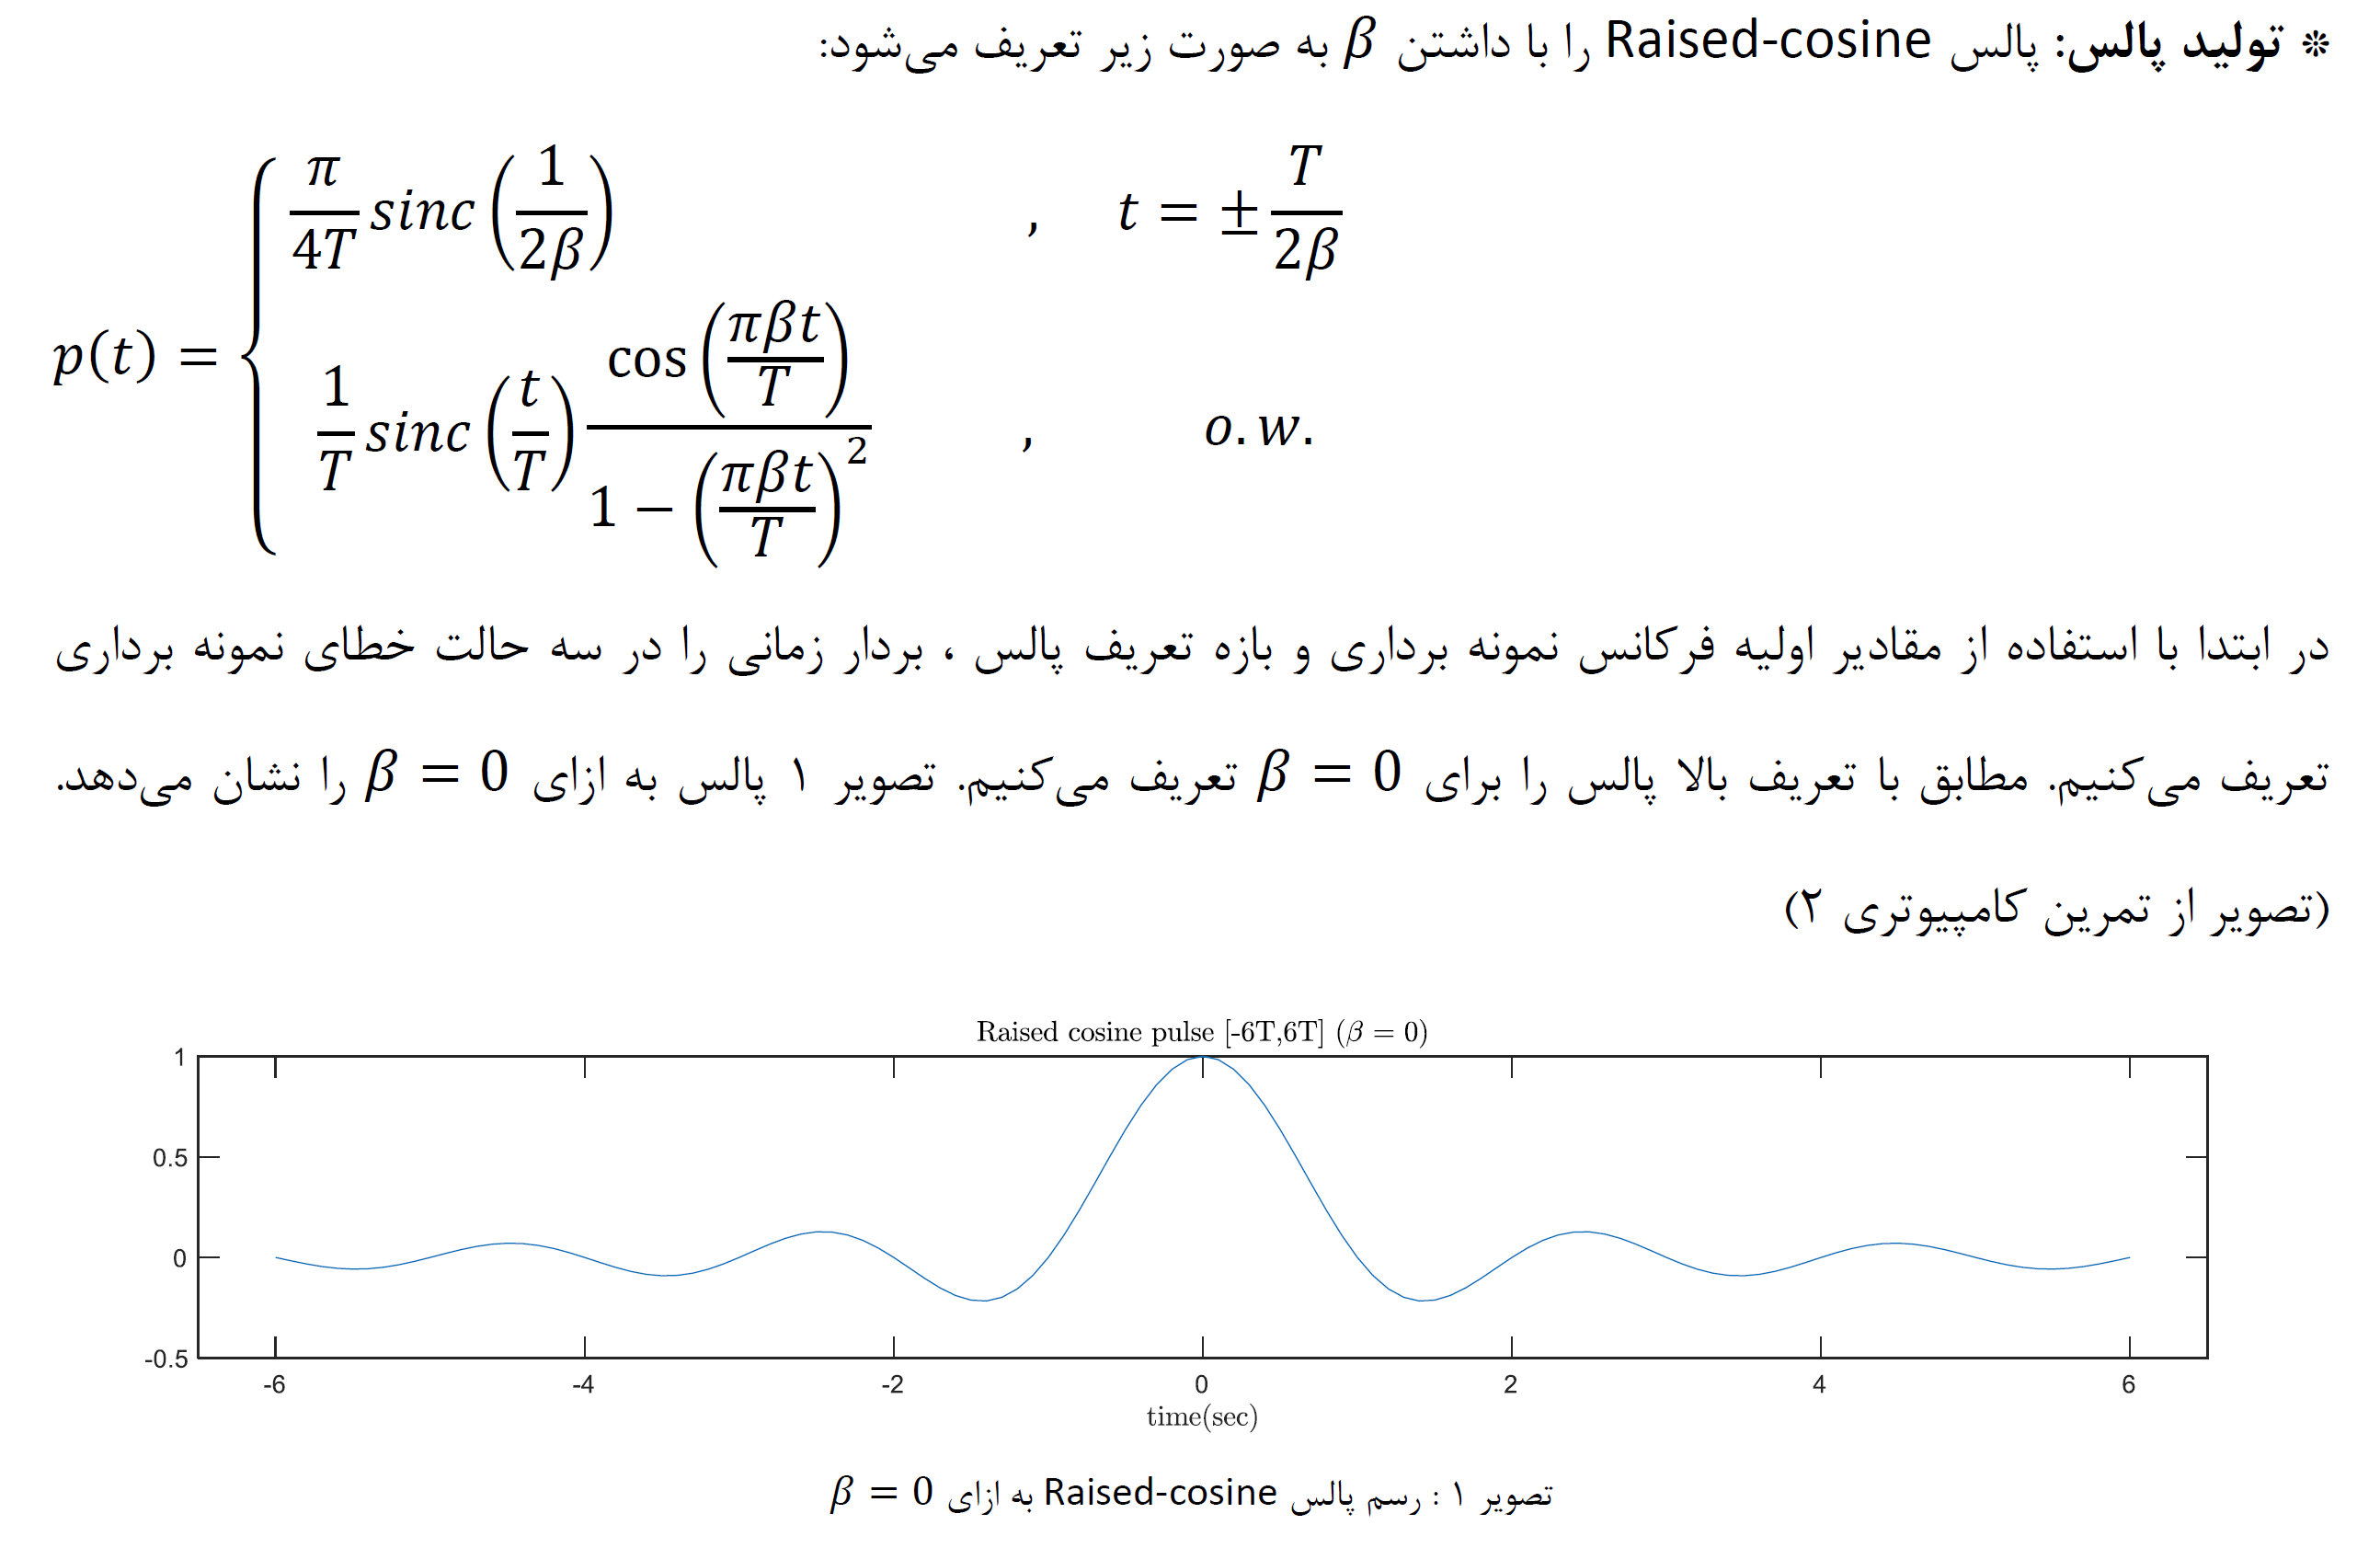

beta = 0;
T = 1;
Fs = 10;
L = T*Fs;
t1 = (-6*L:6*L)/Fs;
pulse = 1/T*sinc(t1/T).*cos(pi*beta*t1/T)./(1-(2*beta*t1/T).^2);
i1 = find(abs(t1) == T/(2*beta));
pulse(i1) = pi/4*sinc(1/(2*beta));

`Part 2. (``Generate the transmitted signal``)`

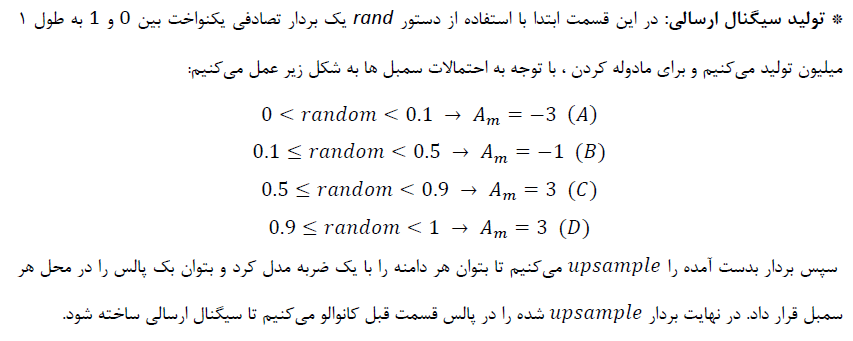

Pr = [0.1 0.4 0.4 0.1];
PR = cumsum(Pr);
N = 1e6;
random_nums = rand(1,N);
modulated_symbols = zeros(1,N);
Am = [-3 -1 1 3];
for i = length(PR):-1:1
    j = random_nums < PR(i);
    modulated_symbols(j) = Am(i);
end
temp0 = upsample(modulated_symbols,L);
temp0 = temp0(1:end-(L-1));
transmitted_signal = conv(pulse,temp0);

`Part 3. (``AWGN Channel Modeling``)`

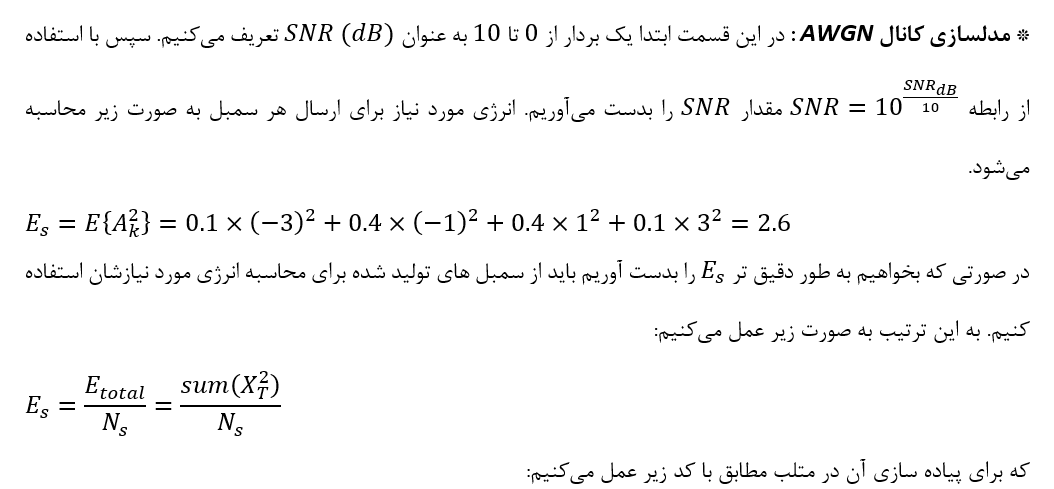

noise = randn(1,length(transmitted_signal));
SNR_dB = 0:10;
SNR = 10.^(SNR_dB/10); % db -> mag
Es = sum(modulated_symbols.^2) / N

Es = 2.6036

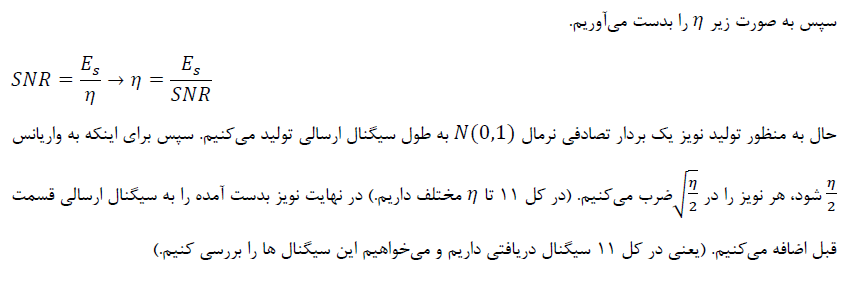

Eta = Es./SNR;
NOISE = sqrt(Eta.'/2) * noise;
received_signal = transmitted_signal + NOISE;

`Part 4. (``Symbols Detection``)`

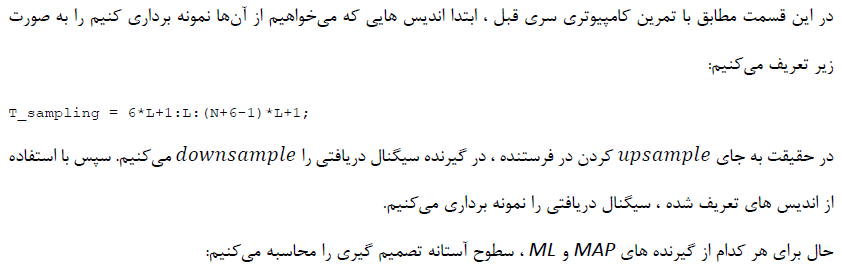

T_sampling = 6*L+1:L:(N+6-1)*L+1;
samples = received_signal(:,T_sampling);

- `MAP Receiver:`

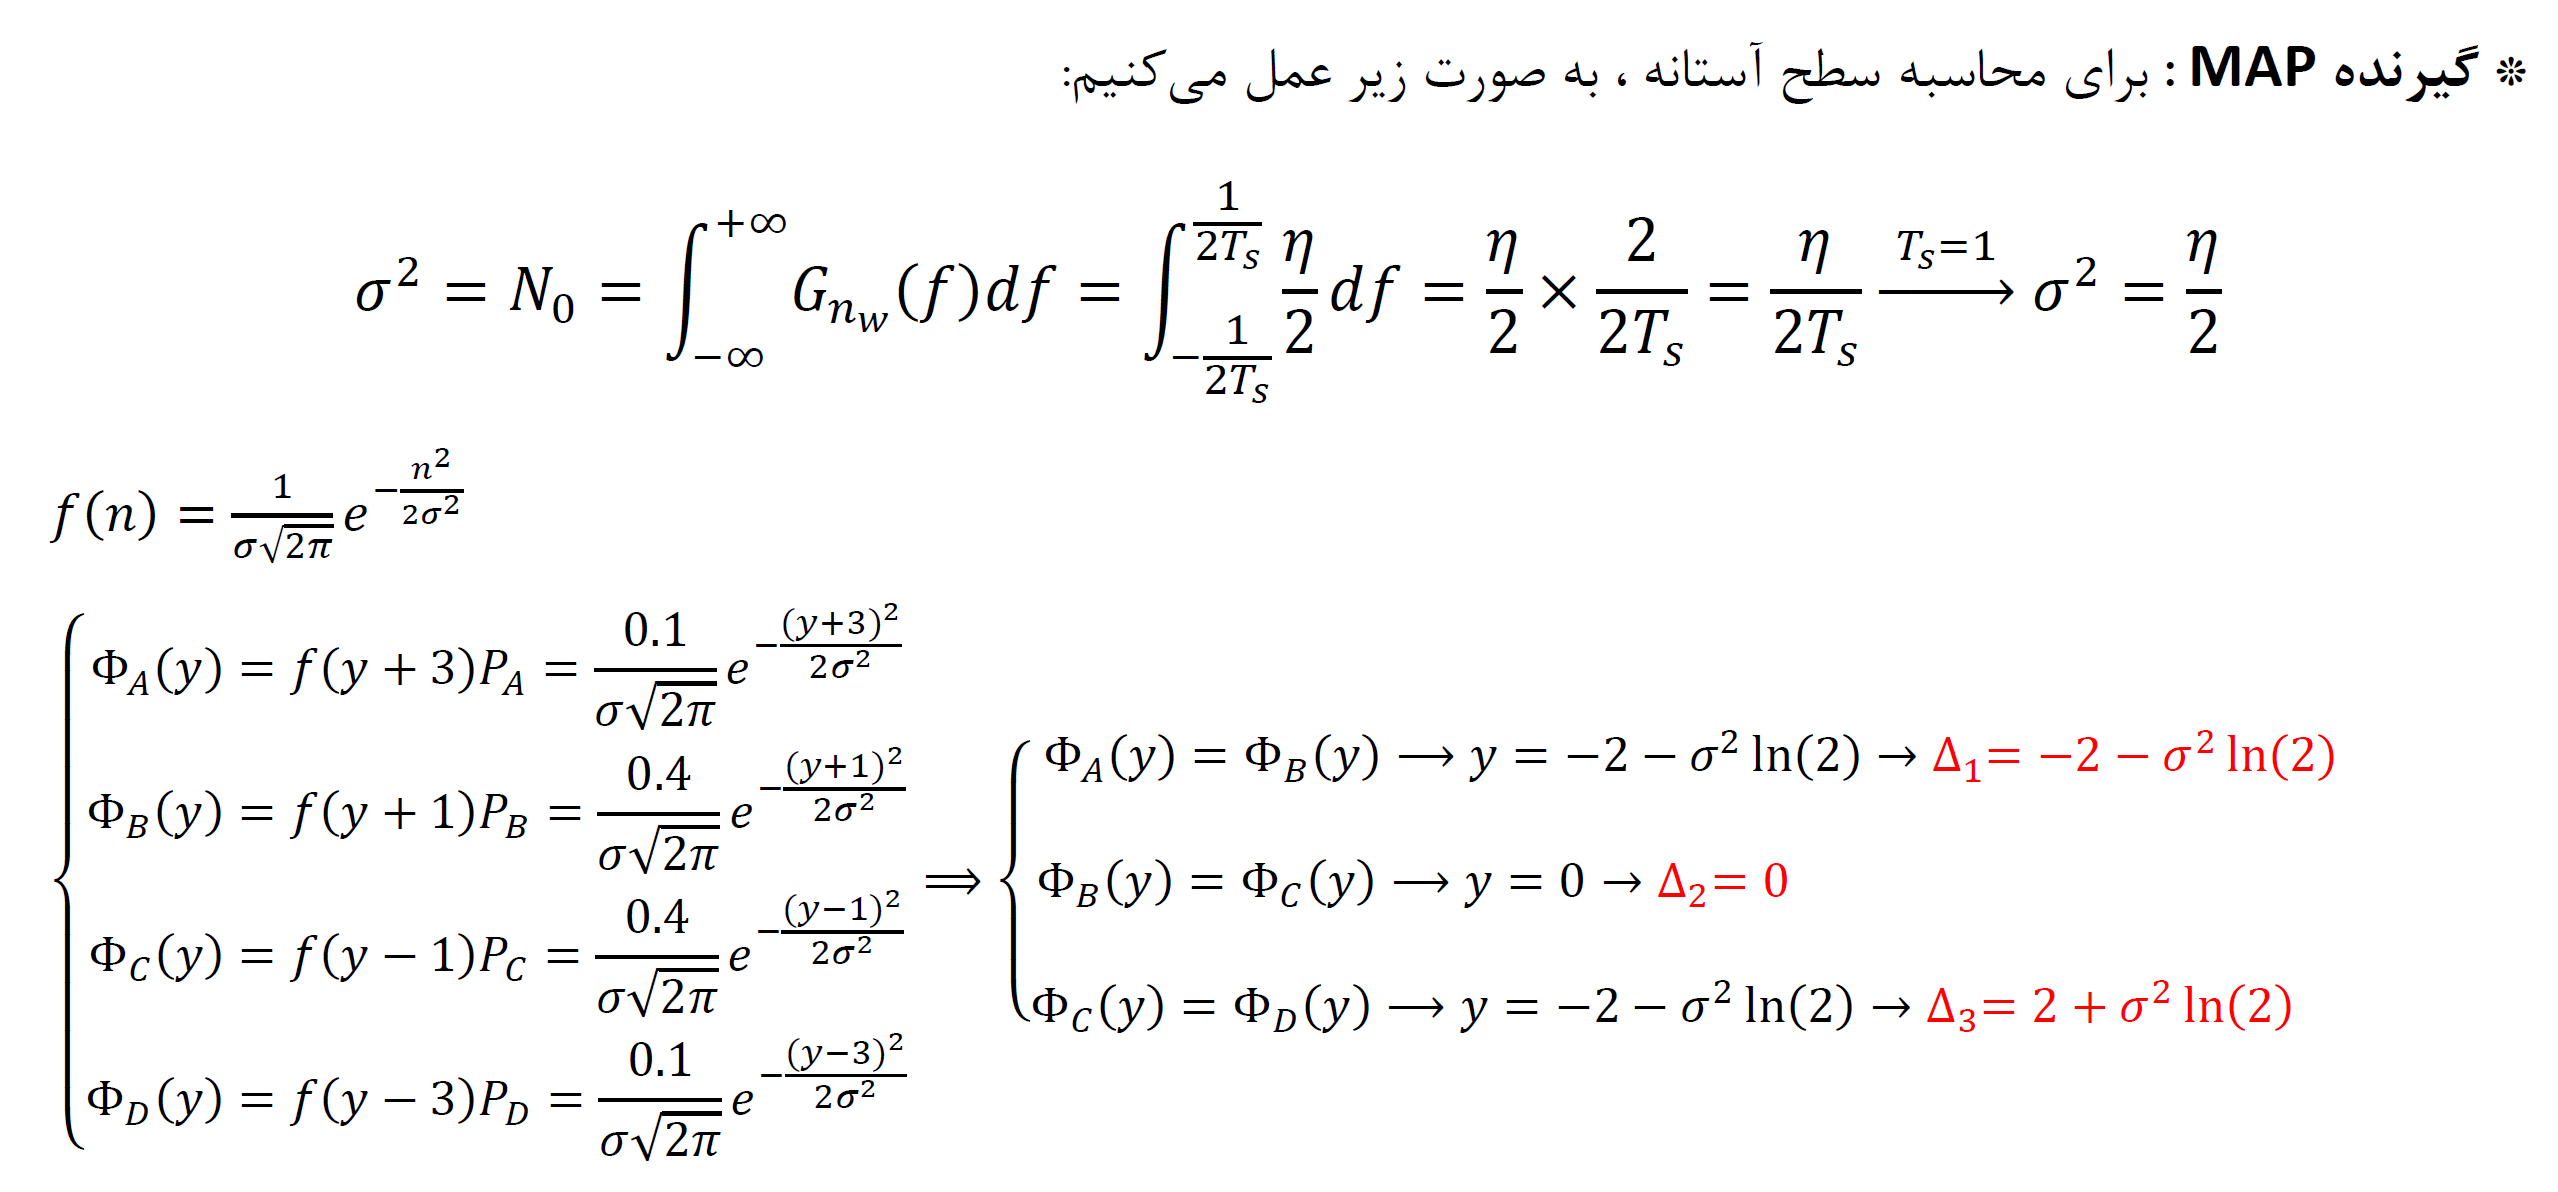

delta1_MAP = -2-(Eta/2).'*log(2);
delta2_MAP = Eta.'*0;
delta3_MAP = 2+(Eta/2).'*log(2);
detected_symbols_MAP = ones(11,length(samples));
j = samples < delta1_MAP;
detected_symbols_MAP(j) = -3;
j = (samples > delta1_MAP) & (samples < delta2_MAP);
detected_symbols_MAP(j) = -1;
j = (samples > delta2_MAP) & (samples < delta3_MAP);
detected_symbols_MAP(j) = 1;
j = samples > delta3_MAP;
detected_symbols_MAP(j) = 3;
correct = detected_symbols_MAP == modulated_symbols;
error_num = N - sum(correct,2);
Pe_MAP = error_num / N;

- `ML Receiver:`

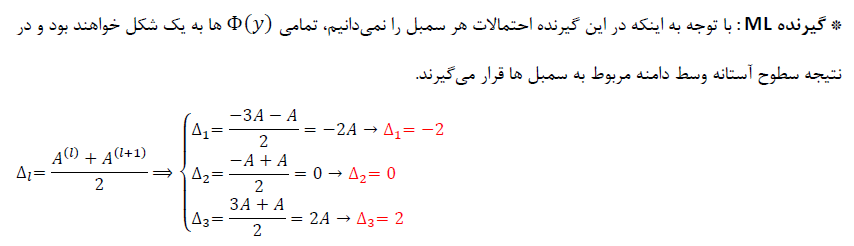

delta_ML = [-2 , 0 , 2];
detected_symbols_ML = ones(11,length(samples));
j = samples < delta_ML(1);
detected_symbols_ML(j) = -3;
j = (samples > delta_ML(1)) & (samples < delta_ML(2));
detected_symbols_ML(j) = -1;
j = (samples > delta_ML(2)) & (samples < delta_ML(3));
detected_symbols_ML(j) = 1;
j = samples > delta_ML(3);
detected_symbols_ML(j) = 3;
correct = detected_symbols_ML == modulated_symbols;
error_num = N - sum(correct,2);
Pe_ML = error_num / N;

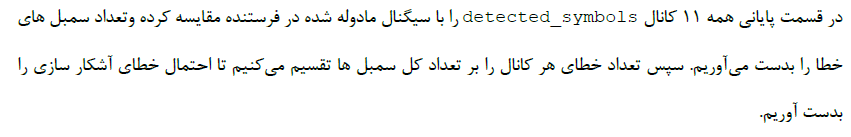

`Part 4. (Figures)`

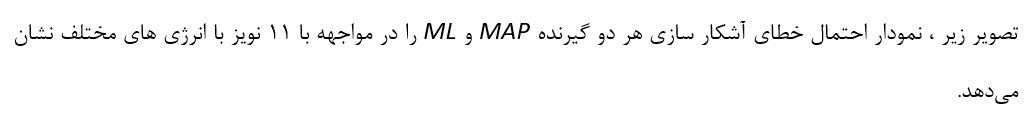

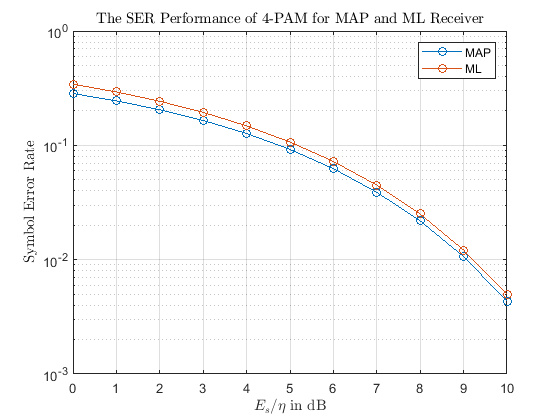

figure
semilogy(SNR_dB,Pe_MAP,'-o',SNR_dB,Pe_ML,'-o');
grid on
ylim([1e-3 1e0]);
legend('MAP','ML');
title('The SER Performance of 4-PAM for MAP and ML Receiver','Interpreter','latex');
xlabel('$E_s/\eta$ in dB','Interpreter','latex');
ylabel('Symbol Error Rate','Interpreter','latex');